# Mailloux算法（按照定义仿真）

Mailloux算法通过由**假想的若干个虚拟干扰源**构造新的协方差矩阵来加宽零陷，从而减小干扰来向变化对阵列性能的影响。

基于均匀线阵的Mailloux算法

以阵元间距为半波长的均匀线阵为例，假设在每个干扰源附近等间隔存在K-1(K>M且为奇数)个等功率的彼此独立的干扰信号，且每个干扰源的来向不变

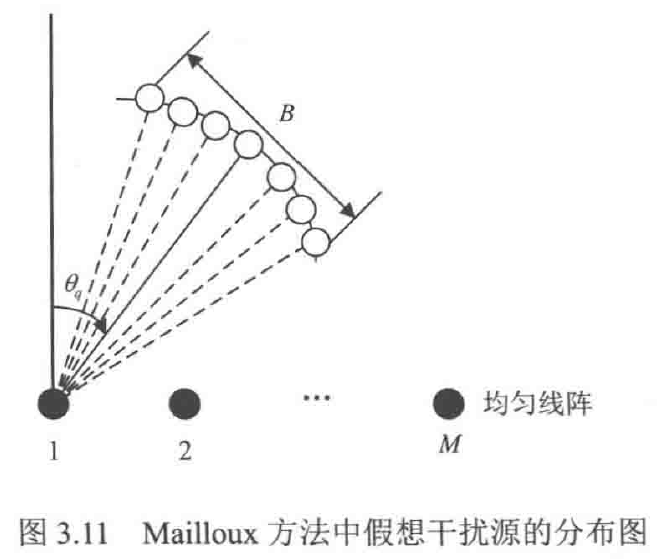

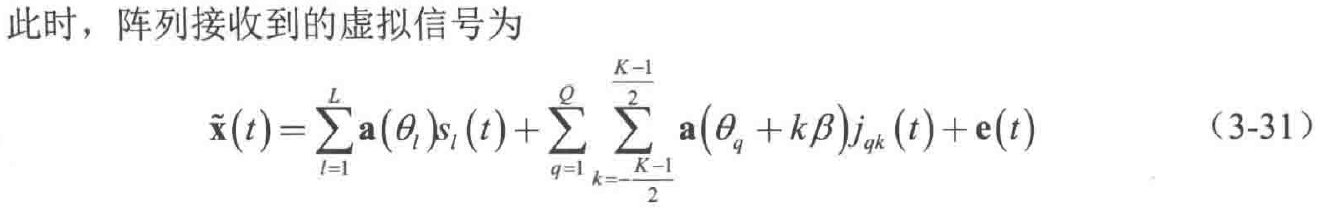

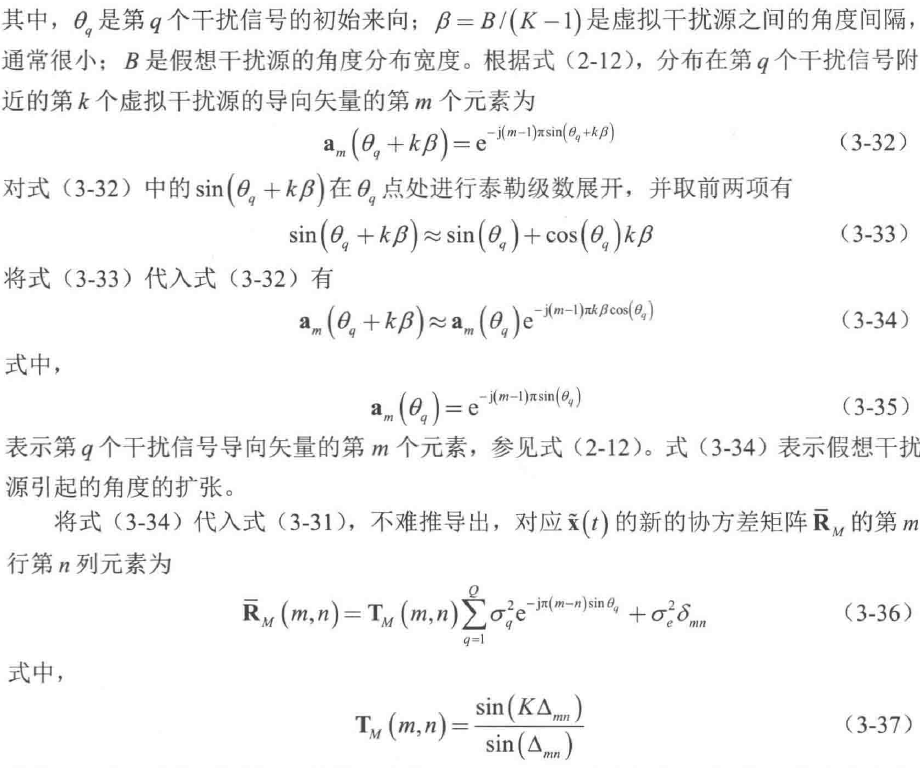

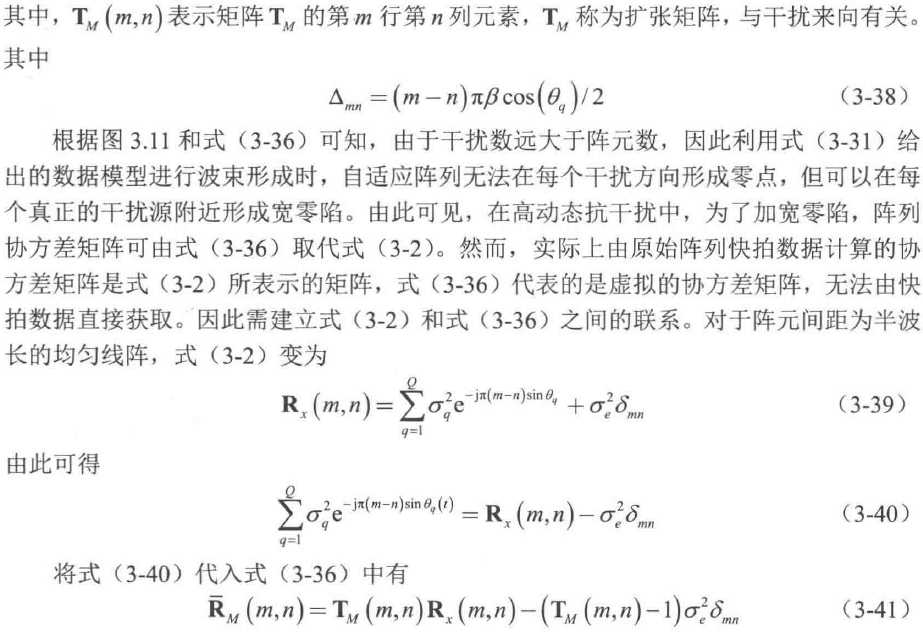

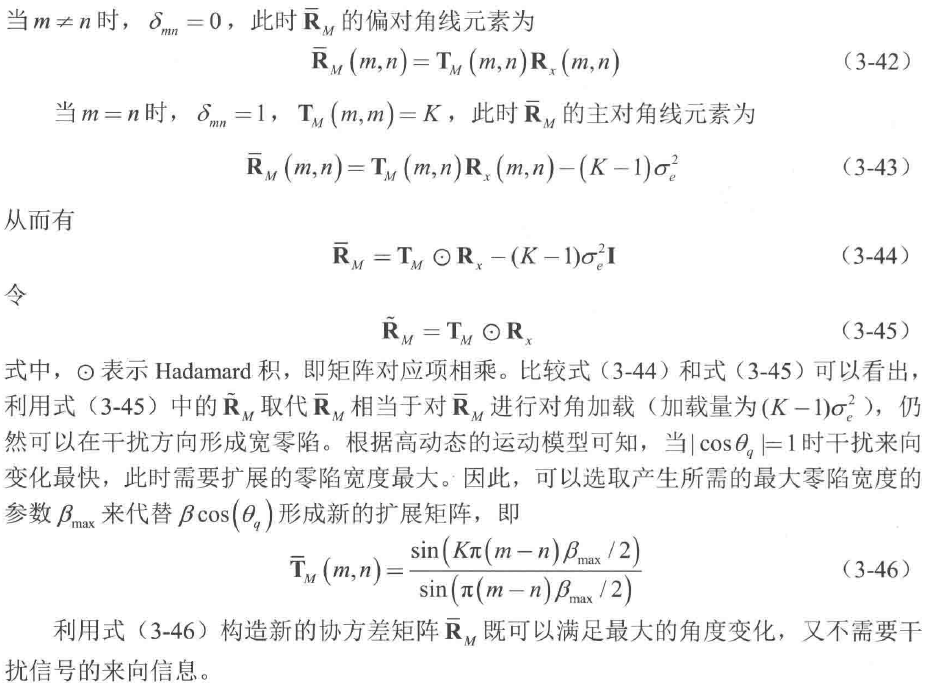

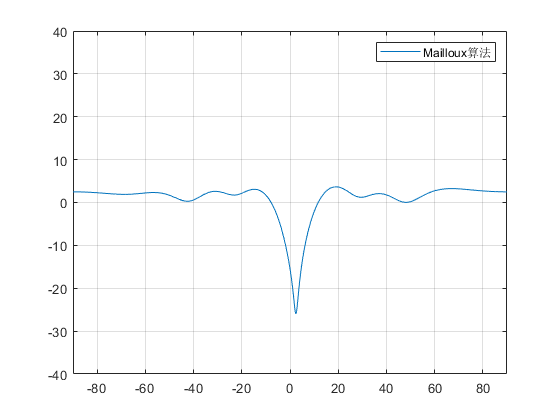

%--------------------------------------------------------------------------
%   初始化
%--------------------------------------------------------------------------
clear;clc;

%--------------------------------------------------------------------------
%   参数设置
%--------------------------------------------------------------------------
N = 8;                                                                     %阵元个数
%--------------------------------------------------------------------------
theta_tgt = [];                                                             %信号来向
%--------------------------------------------------------------------------
B = 5;
K = 11;
beta = B/(K-1);
theta_jam = (0:K-1).*beta;                                                  %干扰拓宽
theta = [theta_tgt theta_jam];
%--------------------------------------------------------------------------
M = numel(theta);                                                           %信源个数
snr = 10;                                                                   %信噪比
K = 1024;                                                                   %采样点数

%--------------------------------------------------------------------------
%   生成3个来向的导向矢量
%--------------------------------------------------------------------------
c = 3e8;                                                                    %光速
lambda = 1;                                                                 %波长
dd = lambda/2;                                                              %阵元间距d = lambda/2
d = 0:dd:(N-1)*dd;                                                          %构建阵列坐标
A = exp(1j.*2*pi*d.'*sind(theta));                                          %构建阵列流形

%--------------------------------------------------------------------------
%   接收信号为随机值
%   并按照阵列流形构造回波相位                                  
%--------------------------------------------------------------------------
S = randn(M,K) + 1j.*randn(M,K);                                            %构建接收信号
S(1,:) = S(1,:).*1;                                                       %信号功率小，干扰功率大,如果信号功率大了 也会默认为干扰位置
X = A*S;                                                                    %对信号来向进行仿真
X1 = awgn(X,snr,'measured');

%--------------------------------------------------------------------------
%   构造接收信号的协方差矩阵
%--------------------------------------------------------------------------
Rx = X1*X1';

%--------------------------------------------------------------------------
%   构造delta_m 约束最小功率
%--------------------------------------------------------------------------
delta_m = zeros(N,1);
delta_m(1) = 1;

%--------------------------------------------------------------------------
%   最优权矢量为
%--------------------------------------------------------------------------
w     = (delta_m'*Rx^-1*delta_m)^-1*(Rx^-1*delta_m);                        %原始结果

%--------------------------------------------------------------------------
%   绘制天线方向图
%--------------------------------------------------------------------------
idx = 1;
for theta_d = -90:0.1:90
    A1 = exp(1j.*2*pi*d.'*sind(theta_d));
    output1(idx) = w'*A1;
    idx = idx + 1;
end

%--------------------------------------------------------------------------
%   计算 信号 干扰角度
%--------------------------------------------------------------------------


figure(1)
plot(-90:0.1:90,db(abs(output1)));grid on;
axis([-90 90 -40 40])
legend('Mailloux算法')